**Grupo 8: Ana Robledano Abasolo, Alfredo Robledano Abasolo, **

**Melani Tatayo Culchas, Rubén Sierra Serrano**

Fecha: 06/05/2023

# **Ejercicio 1**

## Problema T6_7.1. Primera y segunda derivadas en puntos no equiespaciados

clear, clc, clf % Limpieza del entorno de trabajo

a) Escribir una función en Matlab que calcule la primera y segunda derivada de una función que viene dada por un conjunto de puntos discretos desigualmente espaciados.

- Véase PyDerDes.m

b) Utiliza la función creada para resolver el siguiente problema. En la siguiente tabla se da la posición $\left(x,y\right)$ de los coches de una montaña rusa en función del tiempo $t$.

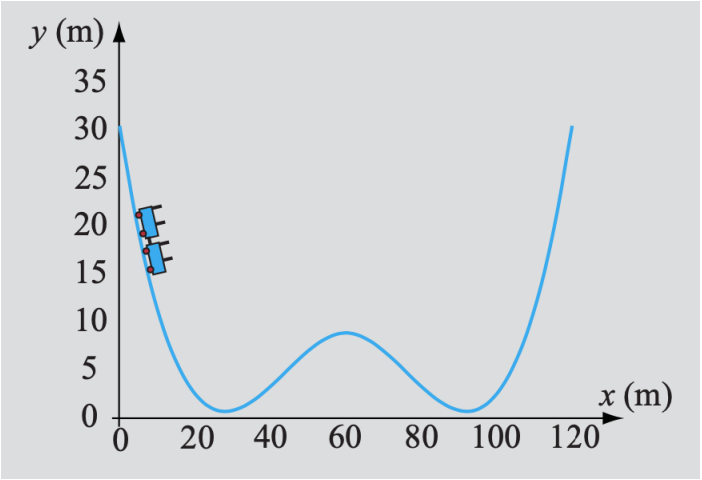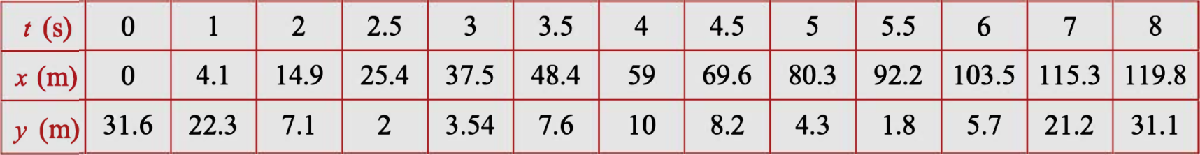

t = [0, 1, 2, 2.5, 3, 3.5, 4, 4.5, 5, 5.5, 6, 7, 8];
x = [0, 4.1, 14.9, 25.4, 37.5, 48.4, 59, 69.6, 80.3, 92.2, 103.5, 115.3, 119.8];
y = [31.6, 22.3, 7.1, 2, 3.54, 7.6, 10, 8.2, 4.3, 1.8, 5.7, 21.2, 31.1];

La velocidad está dada por: 


$$v=\sqrt{{v_x }^2 +{v_y }^2 }$$
            
$$v_x =\frac{\textrm{dx}}{\textrm{dt}}$$
            
$$v_y =\frac{\textrm{dy}}{\textrm{dt}}$$


La acelaración está dada por:


$$a=\sqrt{{a_x }^2 +{a_y }^2 }$$
            
$$a_x =\frac{d^2 x}{\textrm{dt}}$$
            
$$a_y =\frac{d^2 y}{\textrm{dt}}$$


b.1) Calcula la velocidad y la aceleración para cada instante t. Da el resultado en una tabla donde las columnas sean: t(s), x(m), y(m), v(m/s), a(m/s²)

Usando PySDerDes obtenemos los valores de la velocidad y aceleración en los puntos dato

[xd, xdd] = PySDerDes(t, x);
[yd, ydd] = PySDerDes(t, y);
v = sqrt(xd.^2+yd.^2);
a = sqrt(xdd.^2+ydd.^2);

Guardamos en una tabla los resultados obtenidos

res = table( ...
    num2str(t', '%.2f'), ...
    num2str(x', '%.2f'), ...
    num2str(y', '%.2f'),...
    num2str(v', '%.4f'), ...
    num2str(a', '%.4f'), ...
    VariableNames={'t(s)', 'x(m)', 'y(m)', 'v(m/s)', 'a(m/s²)'});
disp(res)

    t(s)     x(m)     y(m)     v(m/s)     a(m/s²)
    ____    ______    _____    _______    _______

    0.00      0.00    31.60     6.3941    21.0394
    1.00      4.10    22.30    14.3375     8.9275
    2.00     14.90     7.10    21.2268    16.5750
    2.50     25.40     2.00    22.8787    27.3202
    3.00     37.50     3.54    23.6719    11.1645
    3.50     48.40     7.60    22.4495     6.7476
    4.00     59.00    10.00    21.2085    16.8000
    4.50     69.60     8.20    22.0495     8.4095
    5.00     80.30     4.30    23.4887     7.3756
    5.50     92.20     1.80    23.2422    25.7123
    6.00    103.50     5.70    21.6441    20.7583
    7.00    115.30    21.20    15.0901     9.2005
    8.00    119.80    31.10     7.1507    24.6702



b.2) Dibuja (tres gráficas en la misma página) las gráficas de $y=f\left(x\right)$    $v=v\left(t\right)$    $a=a\left(t\right)$

Límites de las gráficas

l1_x = min(x); l2_x = max(x);
xx = linspace(l1_x, l2_x);
l1_t = min(t); l2_t = max(t);
tt = linspace(l1_t, l2_t);

Realizamos 3 subplots para tener las gráficas en la misma página

Subplot de posición (x, y)

subplot(3, 1, 1)
plot(x, y,'b.', MarkerSize=12);
pp = spline(x, y);
yy = ppval(pp, xx);
hold on
plot(xx, yy, 'b-')
title('Posición m')
xlabel('x'); ylabel('y(x)')
hold off

Subplot de velocidad v(t)

subplot(3, 1, 2)
plot(t, v, 'r.', MarkerSize=12)
pp = spline(t, v);
yy = ppval(pp, tt);
hold on
plot(tt, yy, 'r-')
title('Velocidad m/s')
xlabel('t'); ylabel('v(t)')
hold off

Subplot de aceleración a(t)

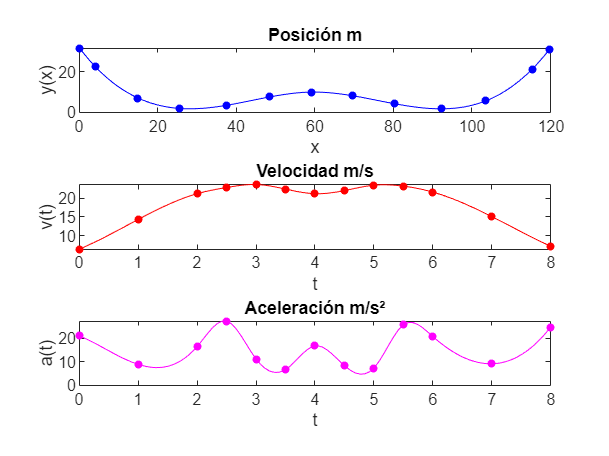

subplot(3, 1, 3)
plot(t, a, 'm.', MarkerSize=12)
pp = spline(t, a);
yy = ppval(pp, tt);
hold on
plot(tt, yy, 'm-')
title('Aceleración m/s²')
xlabel('t'); ylabel('a(t)')
hold off

# **Ejercicio 2**

## T6_7E2. Primeras derivadas parciales

clear, clc, clf % Limpieza del entorno de trabajo

a) Escribe una función en Matlab que evalúe las primeras derivadas

parciales$\frac{\partial }{\partial x}f,\frac{\partial }{\partial y}f$ ( de una función 𝑓(𝑥, 𝑦) dada por puntos tabulados discretos con igual espaciado. Utiliza fórmulas de diferencia central de dos puntos en los puntos interiores y fórmulas de diferencia de tres puntos hacia delante y hacia atrás en los puntos extremos.

- Véase PrmDerPar.m

b) Los siguientes datos de la componente (𝑢) de la velocidad en la dirección 𝑥, se obtienen en función de las dos coordenadas 𝑥 e 𝑦:

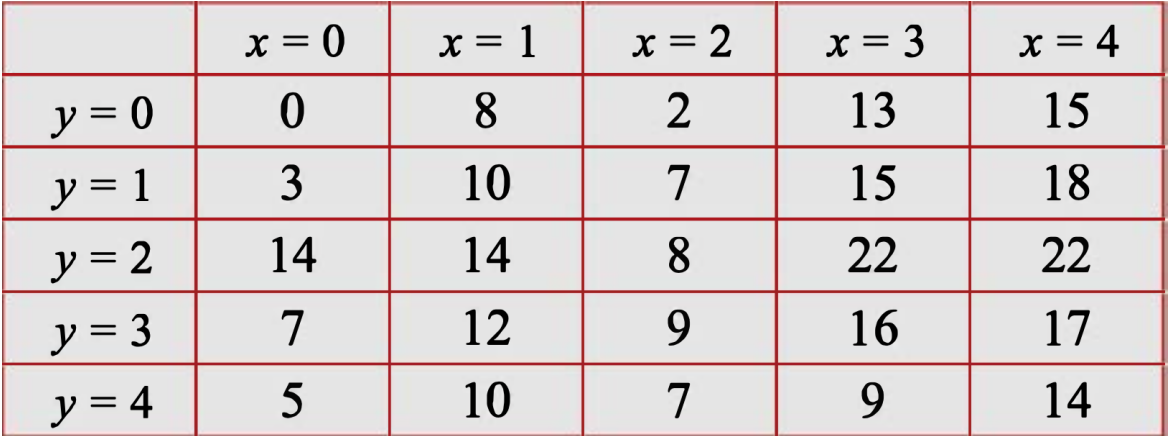

la posición $\left(i,j\right)$ de la matriz de resultados es la derivada en el punto que corresponde a $u\left(x\left(i\right),y\left(j\right)\right)$

x = 0:1:4;
y = 0:1:4;
u = [0 8 2 13 15;
    3 10 7 15 18;
    14 14 8 22 22;
    7 12 9 16 17;
    5 10 7 9 14];

Trabajaremos con x en filas e y en columnas

u = u'

u =      0     3    14     7     5
     8    10    14    12    10
     2     7     8     9     7
    13    15    22    16     9
    15    18    22    17    14


Emplea la funcion `PrmDerPar para calcular las derivadas parciales de u: `$\frac{\partial u}{\partial x},\;\frac{\partial u}{\partial y}$

[dudx,dudy] = PrmDerPar(x, y, u);
disp("Derivada parcial respecto de x:")

Derivada parcial respecto de x:


disp(dudx)

   15.0000   12.0000    3.0000    9.0000    9.0000
    1.0000    2.0000   -3.0000    1.0000    1.0000
    2.5000    2.5000    4.0000    2.0000   -0.5000
    6.5000    5.5000    7.0000    4.0000    3.5000
   -2.5000    0.5000   -7.0000   -2.0000    6.5000




disp("Derivada parcial respecto de y:")

Derivada parcial respecto de y:


disp(dudy)

   -1.0000    7.0000    2.0000   -4.5000    0.5000
    1.0000    3.0000    1.0000   -2.0000   -2.0000
    7.0000    3.0000    1.0000   -0.5000   -3.5000
   -0.5000    4.5000    0.5000   -6.5000   -7.5000
    2.5000    3.5000   -0.5000   -4.0000   -2.0000



# **Ejercicio 3**

## Problema T6_7.3. Extrapolación de Richardson

clear, clc, clf % Limpieza del entorno de trabajo

a) Crea una función en Matlab para calcular la primera y segunda derivadas de una función dada en forma anónima en un punto 𝑥. mediante extrapolación de Richardson con diferencias centrales de dos puntos para la primera derivada y de tres puntos para la segunda.

- Véase DerRichardson.m

b) Emplea la función anterior para calcular la primera y segunda derivadas de la función $f\left(x\right)={\textrm{xe}}^x$ en el punto $x=2$ comenzando con $\textrm{hin}=0\ldotp 4$ y $N=4$. Calcula el error relativo porcentual calculando analíticamente las derivadas y sustituyendo. Da los resultados en una tabla en la que aparezcan los valores de cada derivada calculados mediante Matlab y con el algoritmo de Richardson y el valor absoluto de su diferencia.

Zona de declaración de variables

fun = @(x) x*exp(x);
x0 = 2;
hin = 0.4;
N = 4;

Cálculo de las derivadas con DerRichardson

[dfdx, d2fdx] = DerRichardson(fun, x0, hin, N)

dfdx =     0.4000   23.1635         0         0         0
    0.2000   22.4142   22.1644         0         0
    0.1000   22.2288   22.1670   22.1672         0
    0.0500   22.1826   22.1672   22.1672   22.1672


d2fdx =     0.4000   30.1516         0         0         0
    0.2000   29.7043   29.5552         0         0
    0.1000   29.5932   29.5562   29.5562         0
    0.0500   29.5655   29.5562   29.5562   29.5562


Los resultados para orden de extrapolación N son los últimos valores de la matrices dfdx y d2fdx

h = dfdx(end, 1);
dfdx = dfdx(end, end);
fprintf("La 1ª derivada obtenida con Richardson es:\n%.4f", dfdx)

La 1ª derivada obtenida con Richardson es:
22.1672

d2fdx = d2fdx(end, end);
fprintf("La 2ª derivada obtenida con Richardson es:\n%.4f", d2fdx)

La 2ª derivada obtenida con Richardson es:
29.5562

Se calculan las derivadas analíticas con MatLab

syms x
dfdx_matlab = diff(fun(x), x);
d2fdx_matlab = diff(fun(x), x, 2);
dfdx_matlab = double(subs(dfdx_matlab, x, x0));
fprintf("La 1ª derivada obtenida con MatLab es:\n%.4f", dfdx_matlab)

La 1ª derivada obtenida con MatLab es:
22.1672

d2fdx_matlab = double(subs(d2fdx_matlab, x, x0));
fprintf("La 2ª derivada obtenida con MatLab es:\n%.4f", d2fdx_matlab)

La 2ª derivada obtenida con MatLab es:
29.5562

Error relativo porcentual entre las derivadas calculadas por MatLab y por Richardson

error_relativo_dfdx = abs(dfdx-dfdx_matlab)/abs(dfdx)*100;
error_relativo_d2fdx = abs(d2fdx-d2fdx_matlab)/abs(d2fdx)*100;
fprintf("Error relativo porcentual en la 1ª derivada:\n%e %%", error_relativo_dfdx)

Error relativo porcentual en la 1ª derivada:
1.622084e-10 %

fprintf("Error relativo porcentual en la 2ª derivada:\n%e %%", error_relativo_d2fdx)

Error relativo porcentual en la 2ª derivada:
3.695006e-11 %

Se calculan las diferencias absolutas entre el resultado de MatLab y el obtenido por Richardson

abs_difdf = abs(dfdx_matlab-dfdx);
abs_difd2f = abs(d2fdx_matlab-d2fdx);

Se guardan en una tabla los resultados

T = table(h, dfdx, dfdx_matlab, abs_difdf, d2fdx, d2fdx_matlab, abs_difd2f);
T.Properties.VariableNames = ["h", ...
    "1ªDer_Richardson", "1ªDer_MatLab", "AbsDif_1ªDer", ...
    "2ªDer_Richardson", "2ªDer_MatLab", "AbsDif_2ªDer"];

Finalmente se muestra la tabla

disp('Resultados:')

Resultados:


disp(T)

     h      1ªDer_Richardson    1ªDer_MatLab    AbsDif_1ªDer    2ªDer_Richardson    2ªDer_MatLab    AbsDif_2ªDer
    ____    ________________    ____________    ____________    ________________    ____________    ____________

    0.05         22.167            22.167        3.5957e-11          29.556            29.556        1.0921e-11 



# **Ejercicio 4**

## Problema T6_7.4. Integración de Simpson 3/8

clear, clc, clf % Limpieza del entorno de trabajo

a) Escribe una función de MATLAB que utilice el método compuesto de  Simpson 3/8 para la integración de una función $f\left(x\right)$ que está dada en forma  anónima (f = @(x)).

- Véase Simpson38.m

b) Utiliza Simpson38 para resolver el siguiente problema: 

(Todos los cálculos se deben realizar con un error menor a ${10}^{-5}$)

Er = 1e-5;

En el diseño de tuberías subterráneas, es necesario estimar la temperatura del  suelo. La temperatura del suelo a distintas profundidades puede estimarse  modelando el suelo como un sólido semi-infinito inicialmente a temperatura  constante.

La temperatura a la profundidad, x, y al tiempo,  t, puede calcularse a partir de la expresión:

donde $T_s$ es la temperatura de la superficie, $T_i$ es  la temperatura inicial del suelo y  $\alpha$= 0.138$\cdot {10}^{-6}$ es la difusión térmica del  suelo. Suponiendo que $T_s$ = −15ºC y $T_i$ = 12ºC

alpha = 0.138*10^-6;
Ts = -15;
Ti = 12;
y = @(u) exp(-u.^2);

b.1) Representa gráficamente la temperatura en función del tiempo a una  profundidad de x = 0,5 m durante 40 días. Utiliza incrementos de 1 día comenzando por un valor de t próximo a cero (pero que no sea cero).

Despejando la ecuación anterior tenemos que:


$$T\left(x,\;t\right)=\left(T_i -T_s \right)\frac{2}{\sqrt{\pi }}\int_0^{\frac{x}{2\sqrt{\alpha \;t}}} e^{{-u}^2 } \textrm{du}+T_s$$


Evaluaremos la función $T\left(x,t\right)$ en $\left(x=0\ldotp 5\right)$ y $\left(0\ldotp 001<t<40\ldotp 001\right)$

x = 0.5; % En metros
t_dias = 0.001:1:40.001; % Días desde 0.001 hasta 40.001 en pasos de 1
t = t_dias*24*60*60; % En segundos

Para calcular la curva de temperatura se realiza la integral para cada valor de t y se sustituye en la ecuación

n = length(t);
I = zeros(n,1);
for i=1:n
    I(i) = Simpson38(y, 0, x/(2*sqrt(alpha*t(i))), Er);
end
T0_5 = (Ti - Ts) * (2/sqrt(pi)) * I  + Ts;

Finalmente se muestra en una gráfica la curva obtenida

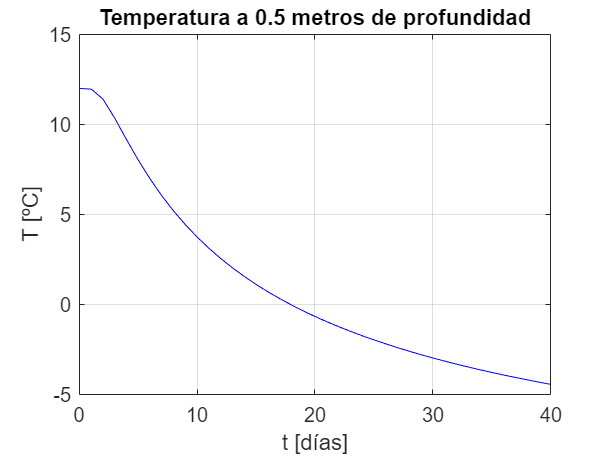

% Límites del dibujo
l1 = 0; l2 = 40;
% Gráfico
plot(t_dias, T0_5, '-b')
hold on
% Documentación y ajustes del gráfico
title('Temperatura a 0.5 metros de profundidad')
xlabel('t [días]'); ylabel('T [ºC]');
xlim([l1, l2]);
grid on
hold off

b.2) Calcula la temperatura a una profundidad x = 1m después de 30 días  (t = 2,592$\cdot {10}^6$)

Evaluaremos la función $T\left(x,t\right)$ en $\left(x=1\right)$ y $\left(t=30\right)$

x = 1; % En metros
t = 2.592e6; % En segundos

I = Simpson38(y, 0, x/(2*sqrt(alpha*t)), Er);
T1_0 = (Ti - Ts) * (2/sqrt(pi)) * I  + Ts;

fprintf("La temperatura a un metro de profundidad tras 30 días es:\n%.2f ºC", T1_0)

La temperatura a un metro de profundidad tras 30 días es:
5.60 ºC

# **Ejercicio 5**

## Problema T6_7.5. Cuadratura de Gauss

clear, clc, clf % Limpieza del entorno de trabajo

a)  Escribe una función de Matlab que calcule cualquier integral definida  mediante la cuadratura de Gauss.

- Véase GaussQ.m

b.1) Escribe un script que calcule las siguientes integrales mediante la  función creada anteriormente con 4 nodos. 

fun1 = @(x) 2*x ./ (1+x.^2);
I1 = GaussQ(fun1, 0, 2.4,4);
fprintf("Valor de I1 calculado con GaussQ:\n%.4f", I1)

Valor de I1 calculado con GaussQ:
1.9104


fun2 = @(x) (sin(x)).^2;
I2 = GaussQ(fun2, 0, pi,4);
fprintf("Valor de I2 calculado con GaussQ:\n%.4f", I2)

Valor de I2 calculado con GaussQ:
1.5691

b.2) Calcula la integral exacta mediante la función integral de Matlab y  con un bucle determina el número de puntos/pesos que debes emplear en la  función GaussQ para obtener el resultado con error menor de ${10}^{-5}$ y da el  resultado de la integral con esos puntos.

Cálculo de la integral con el comando de MATLAB:

syms x
fun = 2*x / (1+x^2);
I1_matlab = double(int(fun, x, 0, 2.4));
fprintf("Valor de I1 calculado con MatLab:\n%.4f", I1)

Valor de I1 calculado con MatLab:
1.9104


fun = (sin(x))^2;
I2_matlab = double(int(fun, x, 0, pi));
fprintf("Valor de I2 calculado con MatLab:\n%.4f", I2)

Valor de I2 calculado con MatLab:
1.5691

Cálculo del error entre el resultado de MATLAB y de la función Simpson38:

- Integral 1

Se calcula el error como el valor absoluto de la diferencia relativa y se llama a Gaussq en un bucle hasta que el error sea menor que ${10}^{-5}$

i = 0;
while abs((I1_matlab - I1)/I1_matlab) >= 1e-5
    I1 = GaussQ(fun1,0,2.4,i);
    i = i + 1;
end
fprintf("El resultado de I1 con %d puntos es:\n%.6f", i,I1)

El resultado de I1 con 7 puntos es:
1.911026

- Integral 2

Misma forma de proceder

while abs((I2_matlab - I2)/I2_matlab) >= 1e-5
    I2 = GaussQ(fun2,0,pi,i);
    i = i + 1;
end
fprintf("El resultado de I2 con %d puntos es:\n%.6f", i, I2)

El resultado de I2 con 8 puntos es:
1.570796

# **Ejercicio 6**

## Problema T6_7.6. Integración de Romberg con trapecios

clear, clc, clf % Limpieza del entorno de trabajo

a) Escribe una función Matlab que utilice el método compuesto de los trapecios para la integración de una función 𝑓(𝑥) que se da en forma analítica (ecuación). 

- Véase Trapeciosn.m

b) Crea una función de Matlab que calcule la integral de una función dada en forma analítica, mediante el método de Romberg.

- Véase Romberg.m

La función llama a la función `Trapecios``n` para calcular las integrales

c)

c.1) Calcula la integral mediante tres niveles de integración de Romberg.


$$\int_0^1 \frac{1}{1+x}\textrm{dx}$$


Utiliza un tamaño inicial de $h=1$ (un subintervalo).

Declaración de variables:

f = @(x) 1./(1+x);
a = 0;
b = 1;
Ni = 1;
Niveles = 3;

Aplicamos Romberg y mostramos el resultado:

IR = Romberg(f, a, b, Ni, Niveles);
I_romberg = IR(1,1);
fprintf("Valor de la integral por Romberg:\n%.2f",I_romberg)

Valor de la integral por Romberg:
0.75

c.2) Compara el resultado obtenido con la integral exacta (calcula el error relativo porcentual)

Tomamos el resultado de la función integral() de MatLab como el valor exacto

I_matlab = integral(f,a,b);
fprintf("Valor de la integral por MatLab:\n%.2f\n", I_matlab)

Valor de la integral por MatLab:
0.69


error = abs((I_matlab - I_romberg)/I_matlab);
fprintf("El error relativo porcentual es del %.1f%%", error*100)

El error relativo porcentual es del 8.2%

c.3) ¿Cuántos subintervalos serán necesarios si empleamos el método compuesto de los trapecios para obtener la misma precisión?

Aplicamos el método de los trapecios hasta sacar el mismo error

% Se incrementa el número de subintervalos hasta que el error sea menor o igual al error obtenido con el método de Romberg
i = 1;
I_trapecios = Trapeciosn(f, a, b, i);
while abs((I_matlab - I_trapecios) / I_matlab) > error
    I_trapecios = Trapeciosn(f, a, b, i);
    i = i + 1;
end
fprintf("Se necesitaron %d subintervalo/s para obtener la misma precisión", i)

Se necesitaron 1 subintervalo/s para obtener la misma precisión

fprintf("Valor de la integral por método de los trapecios:\n%.2f\n", I_trapecios)

Valor de la integral por método de los trapecios:
0.75
